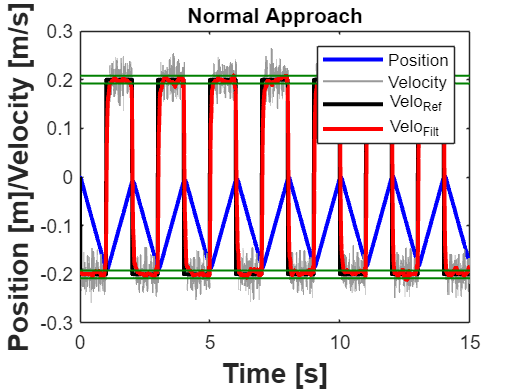

clear 
load("normal.mat")
figure;
h1 = plot(time, position, 'b', 'Linewidth', 2, 'DisplayName', 'Position');
hold on;
h2 = plot(time, velocity, 'Linewidth', 1, 'Color', [0.6, 0.6, 0.6], 'DisplayName', 'Velocity'); 
h3 = plot(time, velocity_ref, 'k', 'Linewidth', 2, 'DisplayName', 'Velo_{Ref}');
h4 = plot(time, velocity_filt, 'r', 'Linewidth', 2, 'DisplayName', 'Velo_{Filt}');

xlabel('Time [s]', 'FontWeight', 'bold', 'FontSize', 14)
ylabel('Position [m]/Velocity [m/s]', 'FontWeight', 'bold', 'FontSize', 14);
title("Normal Approach");

% Plot +/-2% bands without including them in the legend
plot(time_ival, ref_ival+band_ival, time_ival, ref_ival-band_ival, ...
     time_ival, -ref_ival+band_ival, time_ival, -ref_ival-band_ival, ...
     'LineWidth', 1, 'color', [0, 0.5, 0]);

hold off;

% Specify the plots to include in the legend using their handles
legend([h1, h2, h3, h4]);

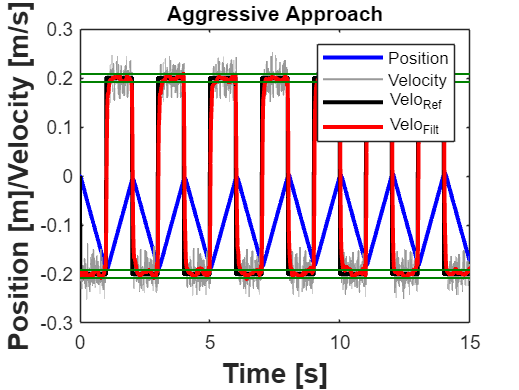

clear;
load("aggressive.mat");

% Assign plots to handles
h1 = plot(time, position, 'b', 'Linewidth', 2, 'DisplayName', 'Position');
hold on;
h2 = plot(time, velocity, 'Linewidth', 1, 'Color', [0.6, 0.6, 0.6], 'DisplayName', 'Velocity'); 
h3 = plot(time, velocity_ref, 'k', 'Linewidth', 2, 'DisplayName', 'Velo_{Ref}');
h4 = plot(time, velocity_filt, 'r', 'Linewidth', 2, 'DisplayName', 'Velo_{Filt}');

xlabel('Time [s]', 'FontWeight', 'bold', 'FontSize', 14);
ylabel('Position [m]/Velocity [m/s]', 'FontWeight', 'bold', 'FontSize', 14);
title("Aggressive Approach");

% Plot +/-2% bands without 'DisplayName' to exclude them from legend
plot(time_ival, ref_ival + band_ival, time_ival, ref_ival - band_ival, ...
     time_ival, -ref_ival + band_ival, time_ival, -ref_ival - band_ival, ...
     'LineWidth', 1, 'color', [0, 0.5, 0]);

% Use handles to explicitly specify plots for the legend
legend([h1, h2, h3, h4]);

hold off;

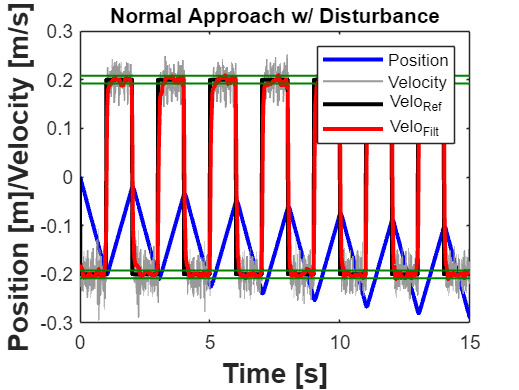

clear;
load("normal_slanted.mat");

% Assign plots to handles for inclusion in the legend
h1 = plot(time, position, 'b', 'Linewidth', 2, 'DisplayName', 'Position');
hold on;
h2 = plot(time, velocity, 'Linewidth', 1, 'Color', [0.6, 0.6, 0.6], 'DisplayName', 'Velocity'); 
h3 = plot(time, velocity_ref, 'k', 'Linewidth', 2, 'DisplayName', 'Velo_{Ref}');
h4 = plot(time, velocity_filt, 'r', 'Linewidth', 2, 'DisplayName', 'Velo_{Filt}');

xlabel('Time [s]', 'FontWeight', 'bold', 'FontSize', 14);
ylabel('Position [m]/Velocity [m/s]', 'FontWeight', 'bold', 'FontSize', 14);
title("Normal Approach w/ Disturbance");

% Plot +/-2% bands without 'DisplayName' to exclude them from legend
plot(time_ival, ref_ival + band_ival, time_ival, ref_ival - band_ival, ...
     time_ival, -ref_ival + band_ival, time_ival, -ref_ival - band_ival, ...
     'LineWidth', 1, 'color', [0, 0.5, 0]);

% Use handles to explicitly specify plots for the legend
legend([h1, h2, h3, h4]);

hold off;

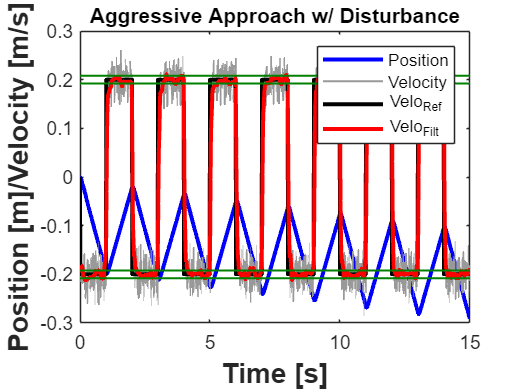

clear;
load("aggresive_slanted.mat");

% Assign plots to handles for inclusion in the legend
h1 = plot(time, position, 'b', 'Linewidth', 2, 'DisplayName', 'Position');
hold on;
h2 = plot(time, velocity, 'Linewidth', 1, 'Color', [0.6, 0.6, 0.6], 'DisplayName', 'Velocity'); 
h3 = plot(time, velocity_ref, 'k', 'Linewidth', 2, 'DisplayName', 'Velo_{Ref}');
h4 = plot(time, velocity_filt, 'r', 'Linewidth', 2, 'DisplayName', 'Velo_{Filt}');

xlabel('Time [s]', 'FontWeight', 'bold', 'FontSize', 14);
ylabel('Position [m]/Velocity [m/s]', 'FontWeight', 'bold', 'FontSize', 14);
title("Aggressive Approach w/ Disturbance");

% Plot +/-2% bands without 'DisplayName' to exclude them from legend
plot(time_ival, ref_ival + band_ival, time_ival, ref_ival - band_ival, ...
     time_ival, -ref_ival + band_ival, time_ival, -ref_ival - band_ival, ...
     'LineWidth', 1, 'color', [0, 0.5, 0]);

% Use handles to explicitly specify plots for the legend
legend([h1, h2, h3, h4]);

hold off;